% 参数设置
c = physconst("LightSpeed");
frequency = 7.9872e9;
lambda = c / frequency;
antennaSpacing = lambda * 0.5;
phase_offset = 0.17;

% 目标角度
target_main_angle = 45;  % 主峰目标角度45°
target_secondary_angle = 0;  % 次峰目标角度0°

% 初始化存储文件信息的结构体
file_info = struct();

% 设置数据文件夹路径
data_folder = '.\\Data\\data_for_doubleAOA_new\\\localization\\processed_rtt_files\\';

% 获取文件夹下所有符合命名规则的文件
file_pattern = 'processed_test60_*.txt';
file_list = dir(fullfile(data_folder, file_pattern));

% 如果没有找到文件，尝试其他命名格式
if isempty(file_list)
    file_pattern = 'test60_*.txt';
    file_list = dir(fullfile(data_folder, file_pattern));
end

fprintf('找到 %d 个文件\n', length(file_list));

找到 3 个文件



% 第一步：遍历所有文件，找到最接近目标角度的文件
best_file_idx = 0;
best_score = inf;

for file_idx = 1:length(file_list)
    filename = fullfile(data_folder, file_list(file_idx).name);
    
    % 检查文件是否存在
    if ~exist(filename, 'file')
        fprintf('文件不存在: %s\n', filename);
        continue;
    end
    
    fprintf('正在分析文件: %s\n', filename);
    
    % 读取文件
    fid = fopen(filename, 'r');
    rawData = textscan(fid, '%s', 'Delimiter', '\n');
    fclose(fid);
    lines = rawData{1};
    
    % 解析文件内容，提取CIR数据
    sn_len = [];
    Ipatov_CIR = [];
    STS0_CIR = [];
    STS1_CIR = [];
    
    current_mode = '';
    inside_CIR_block = false;
    
    for i = 1:length(lines)
        line = strtrim(lines{i});
        
        if contains(line, 'Sequence Number')
            tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
            if ~isempty(tokens)
                sn_len = [sn_len, str2double(tokens{1}{1})];
            end
        end
        
        if contains(line, 'Printing Ipatov CIR')
            current_mode = 'Ipatov';
            inside_CIR_block = false;
        elseif contains(line, 'Printing STS0 CIR')
            current_mode = 'STS0';
            inside_CIR_block = false;
        elseif contains(line, 'Printing STS1 CIR')
            current_mode = 'STS1';
            inside_CIR_block = false;
        end
        
        if contains(line, '_________________________________')
            inside_CIR_block = ~inside_CIR_block;
            continue;
        end
        
        if inside_CIR_block
            data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
            if ~isempty(data_tokens)
                I_val = str2double(data_tokens{1}{1});
                Q_val = str2double(data_tokens{1}{2});
                complex_val = I_val + 1j * Q_val;
                
                if strcmp(current_mode, 'Ipatov')
                    Ipatov_CIR(end+1, 1) = complex_val;
                elseif strcmp(current_mode, 'STS0')
                    STS0_CIR(end+1, 1) = complex_val;
                elseif strcmp(current_mode, 'STS1')
                    STS1_CIR(end+1, 1) = complex_val;
                end
            end
        end
    end
    
    % 重组CIR数据
    if length(STS0_CIR) >= 512 && length(STS1_CIR) >= 512
        packets_num = floor(length(STS0_CIR)/512);
        STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
        STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';
        
        % 如果包数为奇数，丢弃最后一行
        if mod(packets_num, 2) ~= 0
            STS0_CIR(end, :) = [];
            STS1_CIR(end, :) = [];
            packets_num = packets_num - 1;
        end
        
        % 存储当前文件的PDOA和AoA值
        aoa_pdoa_values_main = [];
        aoa_degree_values_main = [];
        aoa_pdoa_values_secondary = [];
        aoa_degree_values_secondary = [];
        
        % 处理每个数据包
        for i = 1:packets_num
            STS0_data = STS0_CIR(i,:);
            STS1_data = STS1_CIR(i,:);
            
            STS0_magnitude = abs(STS0_data);
            STS1_magnitude = abs(STS1_data);
            
            threshold = 0.1;
            min_peak_distance = 2;
            
            % 找峰值
            [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
            [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);
            
            % 检查是否找到足够的峰值
            if length(locs_STS0) < 2 || length(locs_STS1) < 2
                continue;
            end
            
            % 主峰选择
            peak_index1_STS0 = locs_STS0(1);
            main_peak_magnitude_STS0 = STS0_magnitude(peak_index1_STS0);
            
            search_range = 3;
            threshold_ratio = 0.5;
            
            % 寻找候选次峰
            candidate_peaks_STS0 = [];
            candidate_locs_STS0 = [];
            
            for j = 1:length(locs_STS0)
                if locs_STS0(j) ~= peak_index1_STS0 && ...
                   abs(locs_STS0(j) - peak_index1_STS0) <= search_range && ...
                   STS0_magnitude(locs_STS0(j)) >= threshold_ratio * main_peak_magnitude_STS0
                    candidate_peaks_STS0(end+1) = STS0_magnitude(locs_STS0(j));
                    candidate_locs_STS0(end+1) = locs_STS0(j);
                end
            end
            
            if ~isempty(candidate_peaks_STS0)
                [~, max_idx] = max(candidate_peaks_STS0);
                peak_index2_STS0 = candidate_locs_STS0(max_idx);
            else
                post_main_peaks_STS0 = locs_STS0(locs_STS0 > peak_index1_STS0);
                if isempty(post_main_peaks_STS0)
                    continue;
                end
                [~, max_idx] = max(STS0_magnitude(post_main_peaks_STS0));
                peak_index2_STS0 = post_main_peaks_STS0(max_idx);
            end
            
            % STS1处理
            peak_index1_STS1 = locs_STS1(1);
            main_peak_magnitude_STS1 = STS1_magnitude(peak_index1_STS1);
            
            candidate_peaks_STS1 = [];
            candidate_locs_STS1 = [];
            
            for j = 1:length(locs_STS1)
                if locs_STS1(j) ~= peak_index1_STS1 && ...
                   abs(locs_STS1(j) - peak_index1_STS1) <= search_range && ...
                   STS1_magnitude(locs_STS1(j)) >= threshold_ratio * main_peak_magnitude_STS1
                    candidate_peaks_STS1(end+1) = STS1_magnitude(locs_STS1(j));
                    candidate_locs_STS1(end+1) = locs_STS1(j);
                end
            end
            
            if ~isempty(candidate_peaks_STS1)
                [~, max_idx] = max(candidate_peaks_STS1);
                peak_index2_STS1 = candidate_locs_STS1(max_idx);
            else
                post_main_peaks_STS1 = locs_STS1(locs_STS1 > peak_index1_STS1);
                if isempty(post_main_peaks_STS1)
                    continue;
                end
                [~, max_idx] = max(STS1_magnitude(post_main_peaks_STS1));
                peak_index2_STS1 = post_main_peaks_STS1(max_idx);
            end
            
            % 计算主峰和次峰之间的距离
            peak_distance = abs(peak_index2_STS0 - peak_index1_STS0);
            if peak_distance > 15
                continue;
            end
            
            % 幅度差值判断条件
            a_STS0 = STS0_magnitude(peak_index1_STS0) - STS0_magnitude(peak_index2_STS0);
            a_STS1 = STS1_magnitude(peak_index1_STS1) - STS1_magnitude(peak_index2_STS1);
            
            if sign(a_STS0) ~= sign(a_STS1)
                continue;
            end
            
            a_abs = abs(a_STS0);
            b_abs = abs(a_STS1);
            
            if a_abs == 0 || b_abs == 0
                continue;
            end
            
            min_amplitude_diff = min(a_abs, b_abs);
            amplitude_ratio = abs(a_abs - b_abs) / min_amplitude_diff;
            
            if amplitude_ratio >= 500 % 这里的参数可以调整
                continue;
            end
            
            % 计算PDOA和AoA
            STS0_phase_main = angle(STS0_data(peak_index1_STS1));
            STS1_phase_main = angle(STS1_data(peak_index1_STS1));
            phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
            phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;
            
            theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
            theta_degrees_main = rad2deg(theta_radians_main);
            
            STS0_phase_secondary = angle(STS0_data(peak_index2_STS1));
            STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
            phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
            phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;
            
            theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
            theta_degrees_secondary = rad2deg(theta_radians_secondary);
            
            % 存储结果
            aoa_pdoa_values_main(end+1) = phase_difference_main;
            aoa_degree_values_main(end+1) = theta_degrees_main;
            aoa_pdoa_values_secondary(end+1) = phase_difference_secondary;
            aoa_degree_values_secondary(end+1) = theta_degrees_secondary;
        end
        
        % 计算平均角度
        if ~isempty(aoa_degree_values_main)
            avg_main = mean(aoa_degree_values_main);
            avg_secondary = mean(aoa_degree_values_secondary);
            
            % 计算与目标角度的差距
            score = abs(avg_main - target_main_angle) + abs(avg_secondary - target_secondary_angle);
            
            % 存储文件信息
            file_info(file_idx).filename = file_list(file_idx).name;
            file_info(file_idx).avg_main_angle = avg_main;
            file_info(file_idx).avg_secondary_angle = avg_secondary;
            file_info(file_idx).score = score;
            file_info(file_idx).num_valid_packets = length(aoa_degree_values_main);
            file_info(file_idx).all_main_angles = aoa_degree_values_main;
            file_info(file_idx).all_secondary_angles = aoa_degree_values_secondary;
            file_info(file_idx).packets_num = packets_num;
            
            fprintf('  平均主峰角度: %.2f°, 平均次峰角度: %.2f°, 得分: %.2f\n', avg_main, avg_secondary, score);
            
            % 更新最佳文件
            if score < best_score
                best_score = score;
                best_file_idx = file_idx;
            end
        else
            fprintf('  无有效数据\n');
        end
    else
        fprintf('  数据不足，跳过\n');
    end
end

正在分析文件: .\Data\data_for_doubleAOA_new\localization\processed_rtt_files\processed_test60_1.txt


  平均主峰角度: 54.10°, 平均次峰角度: -3.73°, 得分: 12.83


正在分析文件: .\Data\data_for_doubleAOA_new\localization\processed_rtt_files\processed_test60_2.txt


  平均主峰角度: 50.36°, 平均次峰角度: -4.22°, 得分: 9.57


正在分析文件: .\Data\data_for_doubleAOA_new\localization\processed_rtt_files\processed_test60_3.txt


  平均主峰角度: 49.83°, 平均次峰角度: -4.70°, 得分: 9.53



% 检查是否找到目标文件
if best_file_idx == 0
    fprintf('未找到符合条件的文件！\n');
    return;
end

% 第二步：将目标文件的所有有效packet角度保存到txt文件
fprintf('\n=== 选择的目标文件 ===\n');


=== 选择的目标文件 ===


fprintf('文件名: %s\n', file_info(best_file_idx).filename);

文件名: processed_test60_3.txt


fprintf('平均主峰角度: %.2f°\n', file_info(best_file_idx).avg_main_angle);

平均主峰角度: 49.83°


fprintf('平均次峰角度: %.2f°\n', file_info(best_file_idx).avg_secondary_angle);

平均次峰角度: -4.70°


fprintf('有效数据包数: %d\n', file_info(best_file_idx).num_valid_packets);

有效数据包数: 21



% 获取目标文件的所有角度数据
all_main_angles = file_info(best_file_idx).all_main_angles;
all_secondary_angles = file_info(best_file_idx).all_secondary_angles;

% 创建输出文件名
output_filename = sprintf('target_angles_%s.txt', file_info(best_file_idx).filename);

% 写入txt文件
fid = fopen(output_filename, 'w');
fprintf(fid, '主峰角度(°),次峰角度(°)\n');
for i = 1:length(all_main_angles)
    fprintf(fid, '%.6f,%.6f\n', all_main_angles(i), all_secondary_angles(i));
end
fclose(fid);

fprintf('已将 %d 个数据包的角度写入文件: %s\n', length(all_main_angles), output_filename);

已将 21 个数据包的角度写入文件: target_angles_processed_test60_3.txt.txt


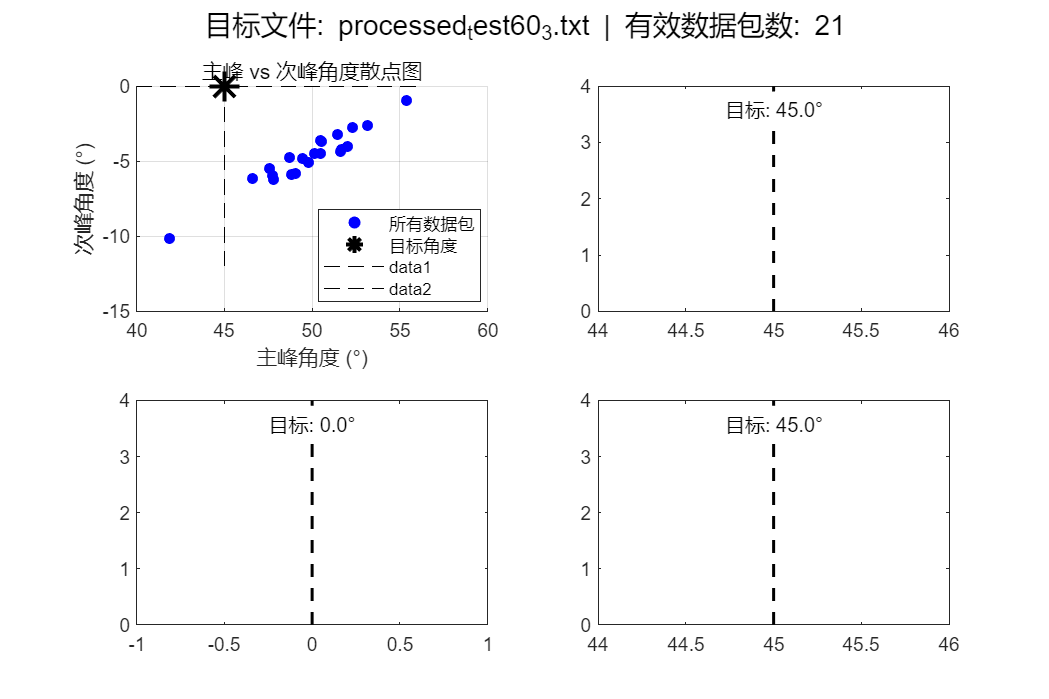


% 第三步：绘制目标文件的统计结果图
figure('Position', [100, 100, 1200, 800]);

% 子图1：所有数据包的主峰和次峰角度散点图
subplot(2, 2, 1);
scatter(all_main_angles, all_secondary_angles, 30, 'b', 'filled', 'DisplayName', '所有数据包');
hold on;
plot(target_main_angle, target_secondary_angle, 'k*', 'MarkerSize', 15, 'LineWidth', 2, 'DisplayName', '目标角度');
xlabel('主峰角度 (°)');
ylabel('次峰角度 (°)');
title('主峰 vs 次峰角度散点图');
legend('Location', 'best');
grid on;

% 添加目标线
plot([target_main_angle target_main_angle], ylim, 'k--', 'LineWidth', 0.5);
plot(xlim, [target_secondary_angle target_secondary_angle], 'k--', 'LineWidth', 0.5);

% 子图2：主峰角度分布
subplot(2, 2, 2);
histogram(all_main_angles, 20, 'FaceColor', 'b', 'EdgeColor', 'black');
xlabel('主峰角度 (°)');
ylabel('频数');
title('主峰角度分布');
grid on;

% 添加目标线
y_limits = ylim;
plot([target_main_angle target_main_angle], y_limits, 'k--', 'LineWidth', 1.5);
text(target_main_angle, y_limits(2)*0.95, sprintf('目标: %.1f°', target_main_angle), ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'BackgroundColor', 'white');

% 子图3：次峰角度分布
subplot(2, 2, 3);
histogram(all_secondary_angles, 20, 'FaceColor', 'b', 'EdgeColor', 'black');
xlabel('次峰角度 (°)');
ylabel('频数');
title('次峰角度分布');
grid on;

% 添加目标线
y_limits = ylim;
plot([target_secondary_angle target_secondary_angle], y_limits, 'k--', 'LineWidth', 1.5);
text(target_secondary_angle, y_limits(2)*0.95, sprintf('目标: %.1f°', target_secondary_angle), ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'BackgroundColor', 'white');

% 子图4：角度差分布
subplot(2, 2, 4);
angle_differences = all_main_angles - all_secondary_angles;
histogram(angle_differences, 20, 'FaceColor', 'b', 'EdgeColor', 'black');
xlabel('角度差 (°)');
ylabel('频数');
title('主峰-次峰角度差分布');
grid on;

% 添加目标线
target_difference = target_main_angle - target_secondary_angle;
y_limits = ylim;
plot([target_difference target_difference], y_limits, 'k--', 'LineWidth', 1.5);
text(target_difference, y_limits(2)*0.95, sprintf('目标: %.1f°', target_difference), ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'BackgroundColor', 'white');

sgtitle(sprintf('目标文件: %s | 有效数据包数: %d', file_info(best_file_idx).filename, length(all_main_angles)), 'FontSize', 14);


% 第四步：显示详细统计信息
fprintf('\n=== 详细统计信息 ===\n');


=== 详细统计信息 ===


fprintf('目标文件 (%d个有效数据包):\n', length(all_main_angles));

目标文件 (21个有效数据包):


fprintf('  主峰角度 - 均值: %.3f°, 标准差: %.3f°, 范围: [%.3f°, %.3f°]\n', ...
    mean(all_main_angles), std(all_main_angles), min(all_main_angles), max(all_main_angles));

  主峰角度 - 均值: 49.832°, 标准差: 2.765°, 范围: [41.881°, 55.355°]


fprintf('  次峰角度 - 均值: %.3f°, 标准差: %.3f°, 范围: [%.3f°, %.3f°]\n', ...
    mean(all_secondary_angles), std(all_secondary_angles), min(all_secondary_angles), max(all_secondary_angles));

  次峰角度 - 均值: -4.697°, 标准差: 1.824°, 范围: [-10.131°, -0.919°]


fprintf('  角度差 - 均值: %.3f°, 标准差: %.3f°\n', mean(angle_differences), std(angle_differences));

  角度差 - 均值: 54.529°, 标准差: 1.129°



% 第五步：显示所有文件的排名
fprintf('\n=== 所有文件排名 (按与目标角度的差距排序) ===\n');


=== 所有文件排名 (按与目标角度的差距排序) ===


% 提取所有有效文件的信息
valid_files = [];
for i = 1:length(file_info)
    if ~isempty(file_info(i).filename)
        valid_files = [valid_files, i];
    end
end

% 按得分排序
scores = zeros(1, length(valid_files));
for i = 1:length(valid_files)
    idx = valid_files(i);
    scores(i) = file_info(idx).score;
end

[sorted_scores, sort_idx] = sort(scores);

fprintf('排名\t文件名\t\t\t\t主峰平均角度\t次峰平均角度\t得分\n');

排名	文件名				主峰平均角度	次峰平均角度	得分


for i = 1:length(sorted_scores)
    idx = valid_files(sort_idx(i));
    filename_short = file_info(idx).filename;
    if length(filename_short) > 15
        filename_short = [filename_short(1:12) '...'];
    end
    fprintf('%d\t%s\t%.2f°\t\t%.2f°\t\t%.2f\n', i, filename_short, ...
        file_info(idx).avg_main_angle, file_info(idx).avg_secondary_angle, sorted_scores(i));
    
    if idx == best_file_idx
        fprintf('   <--- 选择的目标文件\n');
    end
end

1	processed_te...	49.83°		-4.70°		9.53


   <--- 选择的目标文件


2	processed_te...	50.36°		-4.22°		9.57
3	processed_te...	54.10°		-3.73°		12.83



fprintf('\n处理完成！\n');


处理完成！


fprintf('目标文件的所有角度已保存到: %s\n', output_filename);

目标文件的所有角度已保存到: target_angles_processed_test60_3.txt.txt
